This script is full of bugs - find and correct all. You won't need to add any lines, just correct the existing code.

The set of eigenvalues of the last two matrices in the script should be equal and all be in the desired location. 

See the file `QuestionObserverBasedControlHighOrder.pd`f to see what this problem might look like in an exam. 

syms x1 x2 x3 alpha u k1 k2 k3 l1 l2 l3 zeta real
syms s complex

## Suppose you have the following system

Consider the following state-space model for the azimuthal angle of a dish used to track a satellite, where $y$ is the azimuthal angle, $u$ is the input voltage to a power amplifier, used to drive the dish, and $x$ is the state of the system. 


$$\dot{x} = f(x,u) = Ax+Bu$$



$$y = Cx$$


x = [x1; x2; x3];
x1dot = x2;
x2dot = x3;
x3dot = -171*x2-101.71*x3+u

$$x3dot = u-171\,x_{2}-\frac{10171\,x_{3}}{100}$$

f = [x1dot; x2dot; x3dot]

$$f = \left(\begin{array}{c} x_{2}\\ x_{3}\\ u-171\,x_{2}-\frac{10171\,x_{3}}{100} \end{array}\right)$$

y = 1325*x1

$$y = 1325\,x_{1}$$

% linearise about origin
A = subs(jacobian(f,x),{x1 x2 x3 u},{0 0 0 0})

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & -171 & -\frac{10171}{100} \end{array}\right)$$

eig(A) % check: is open-loop system stable?

$$ans = \left(\begin{array}{c} -100\\ -\frac{171}{100}\\ 0 \end{array}\right)$$

B = subs(jacobian(f,u),{x1 x2 x3 u},{0 0 0 0})

$$B = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

C = subs(jacobian(y,x),{x1 x2 x3 u},{0 0 0 0})

$$C = \left(\begin{array}{ccc} 1325 & 0 & 0 \end{array}\right)$$

D = subs(jacobian(y,u),{x1 x2 x3 u},{0 0 0 0})

$$D = 0$$

process = ss(eval(A), eval(B), eval(C), eval(D),'InputName',{'u'}','OutputName','y','StateName',{'x1', 'x2', 'x3'})

process =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3       0    -171  -101.7
 
  B = 
       u
   x1  0
   x2  0
   x3  1
 
  C = 
        x1    x2    x3
   y  1325     0     0
 
  D = 
      u
   y  0
 
Continuous-time state-space model.



### Is the system reachable?

Wr = [B A*B]

$$Wr = \left(\begin{array}{cc} 0 & 0\\ 0 & 1\\ 1 & -\frac{10171}{100} \end{array}\right)$$

detWr = det(Wr)

Error using sym/det (line 24)
Matrix must be square.

rankWr = rank(Wr)
reachableIff = not(simplify(detWr == 0))

## Is the system observable?

Wo = [C; C*A]
rank(Wo)
detWo = det(Wo)
observableIff = not(simplify(detWo == 0))

## Use the separation principle to derive the state feedback and observer gains for a dynamic output feedback controller that places all the poles at a desirable location

### Compute matrix $K$for a state feedback controller $u=-Kx$ to place e/values of state feedback closed-loop dynamics matrix$A-BK$at desired location

n = length(x) % number of states
K = [k1 k2]
ABK = A-B*K

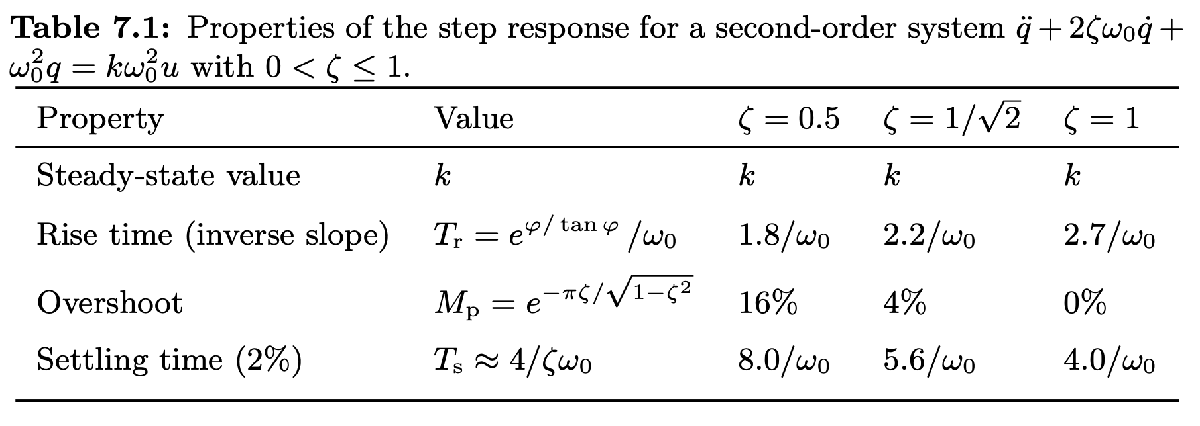

damp(process) % open-loop system
Mp = ...; % desired overshoot should be 10%
Tsettle = 1; % desired 2% settling time should be 1s
zeta = vpasolve(Mp == exp(1/sqrt(1-zeta^2)),zeta) % solve for damping factor from table above
omega = ... % compute natural frequency from table above
pdomc = s^2+2*zeta*omega*s+omega^2 % dominant pair 
solve(pdomc==0,s) % check where the roots are and place third pole 10 times further from imaginary axis than real part of dominant pair
pdABK = expand((s+...)*pdomc) % desired characteristic polynomial for A-B*K where K is a state feedback
pABK = det(s*eye(n)-ABK) % actual characteristic polynomial for A-B*K where K is a state feedback
coeffseqr = coeffs(pABK,s) == coeffs(pdABK,s) % equate coefficients
Ks = solve(coeffseqr,K,"ReturnConditions",true); % solve for K
Ks.conditions % conditions under which a solution exists
K = [Ks.k1 Ks.k2 Ks.k3] 

Incorrect use of '=' operator. To assign a value to a variable, use '='. To compare values for equality, use '=='.

### Compute observer gain $L$ to place eigenvalues of state estimate error dynamics matrix$A-LC$

L = [l1 l2]
ALC(L) = A-L*C
% the desired transient response for the observer should have a 10%
% overshoot and a natural frequency 10 times greater than the closed-loop
% system with a state feedback control as computed above
pdomo = ... % dominant pair
solve(pdomo==0,s) % check where the roots are and place third pole 10 times further from imaginary axis than real part of dominant pair
pdALC = expand((s+400)*pdomo)  % desired characterisic polynomial for observer error dynamics
pALC = det(s*eye(n)-ALC) % actual characterisic polynomial for observer error dynamics
coeffseqo = coeffs(pALC,s) == coeffs(pdALC,s) % equate coefficients
Ls = solve(coeffseqo,L,"ReturnConditions",true); % solve for L
Ls.conditions % conditions under which a solution exists
L = [Ls.l1; Ls.l2; Ls.l3]

## **Compute expression for **observer-based controller

Compute a state space expression for an observer-based controller that has as its inputs $y$ and $r$ and 


$$u=-K\hat{x}+K_fr$$
 

as its output, where $r$ is a given constant reference signal and $\hat{x}$ is an estimate of the state. 

Compute the feedforward gain $K_f$ such that $\lim_{t\rightarrow \infty } y(t) = r$.

p = size(C,1) % number of measured outputs
Kf = -(C*((A-B*K)\B))\eye(p)

m = size(B,2); % number of control inputs
Acontrol = A-B*K;
Bcontrol = [L B*Kf];
Ccontrol = -K;
Dcontrol = [zeros(m,p) Kf];
controller  = ss(eval(Acontrol), eval(Bcontrol), eval(Ccontrol), eval(Dcontrol),'InputName',{'y','r'}','OutputName','u','StateName',{'xhat1', 'xhat2', 'xhat3'})

### Check that eigenvalues of closed-loop dynamics matrix are as desired

Closed-loop dynamics matrix with augmented state as$(x,\hat{x})$:

Aclxandxhat = [A -B*K; L*C A-B*K-L*C];

Closed-loop dynamics matrix with augmented state as$(x,\tilde{x})$, where $\tilde{x}=x-\hat{x}$:

Aclxandxtilde = [A-B*K B*K; zeros(n) A-L*C]; % block upper triangular

Check whether the eigenvalues of the two matrices above are the same and are all at the desired locations

eig(Aclxandxhat)
eig(Aclxandxtilde)

## Explore effect of a constant input disturbance

processdist = ss(eval(A), eval([B B]), eval(C), eval(D),'InputName',{'u', 'disturbance'},'OutputName','y','StateName',{'x1', 'x2', 'x3'})

clsys = connect(processdist,controller,{'r', 'disturbance'},{'y', 'u'});
[Acl,Bcl,Ccl,Dcl] = ssdata(clsys);
eig(Acl) % check whether closed-loop poles are the same as above

damp(processdist) % open-loop system
damp(clsys) % closed-loop system
step(clsys) % closed-loop system
[sig,t] = gensig("square",5,10);
x0 = zeros(n,1);
lsim(clsys,[sig ones(length(t),1)],t,[x0; x0]) % no initial state estimate error, r = sig, d  = 1
lsim(clsys,[0*sig sig],t,[x0; x0]) % no initial state estimate error, r = 0, d = sig
lsim(clsys,[sig 0*sig],t,[x0; x0]) % no initial state estimate error, r = sig, d  = 0